#                    MATLAB Assignment 1

## Goal: Reading a different images and applying  handson  filters

### Resouces: Images (provided by matlab), various filters(provided by laptop)

### procedure:

### 1.Reading images

%First I loaded images into my workspaces

Then using controls I put all images in dropdown box 

**"livescript controls are used( bonus points purpose)"**

%loading all images into image


Image='images/image1.png';

%im=imread("images/image3.jpg");
%Reading image using imread function
im=imread(Image);


### 2.Display Image

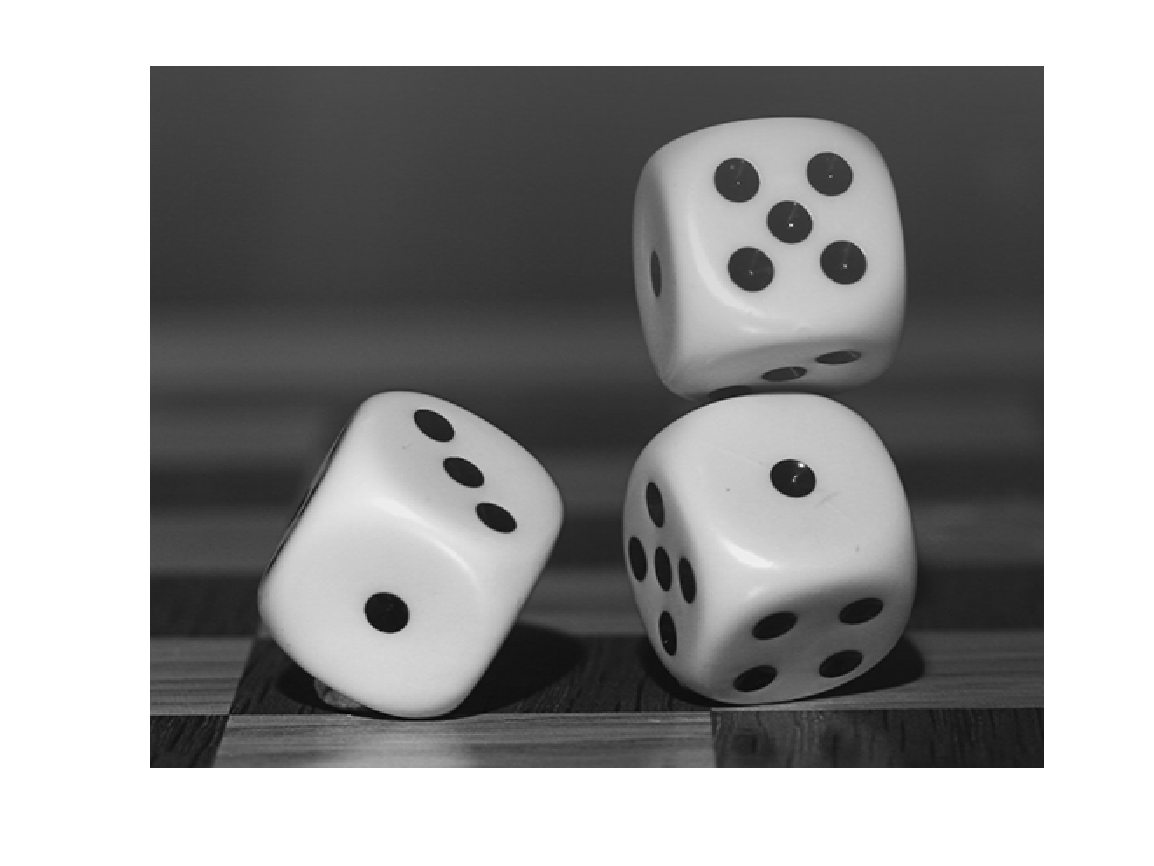

%imshow is a funtion used for showing images
imshow(im)

### 3.Converting RGB image to gray image

%im2gray is a function used to convert images from rgb to gray
Gi=im2gray(im);

### 4.Various type of filters

####      1.Histogram Equalization

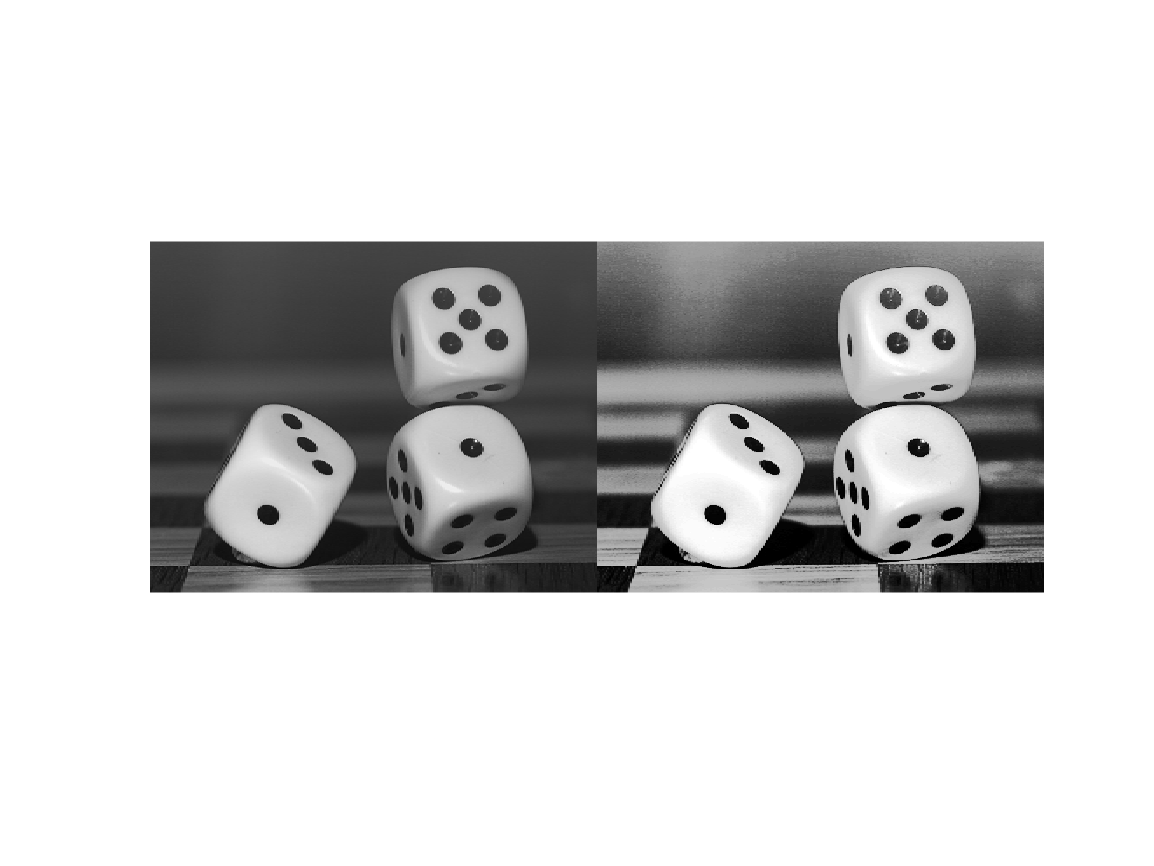

% Performs histogram equalization on grayscale images.
HistEquImage=histeq(Gi);
%imshowpair function shows the two images into side by side
imshowpair(im,HistEquImage,"montage")

####      2.Noise Removal

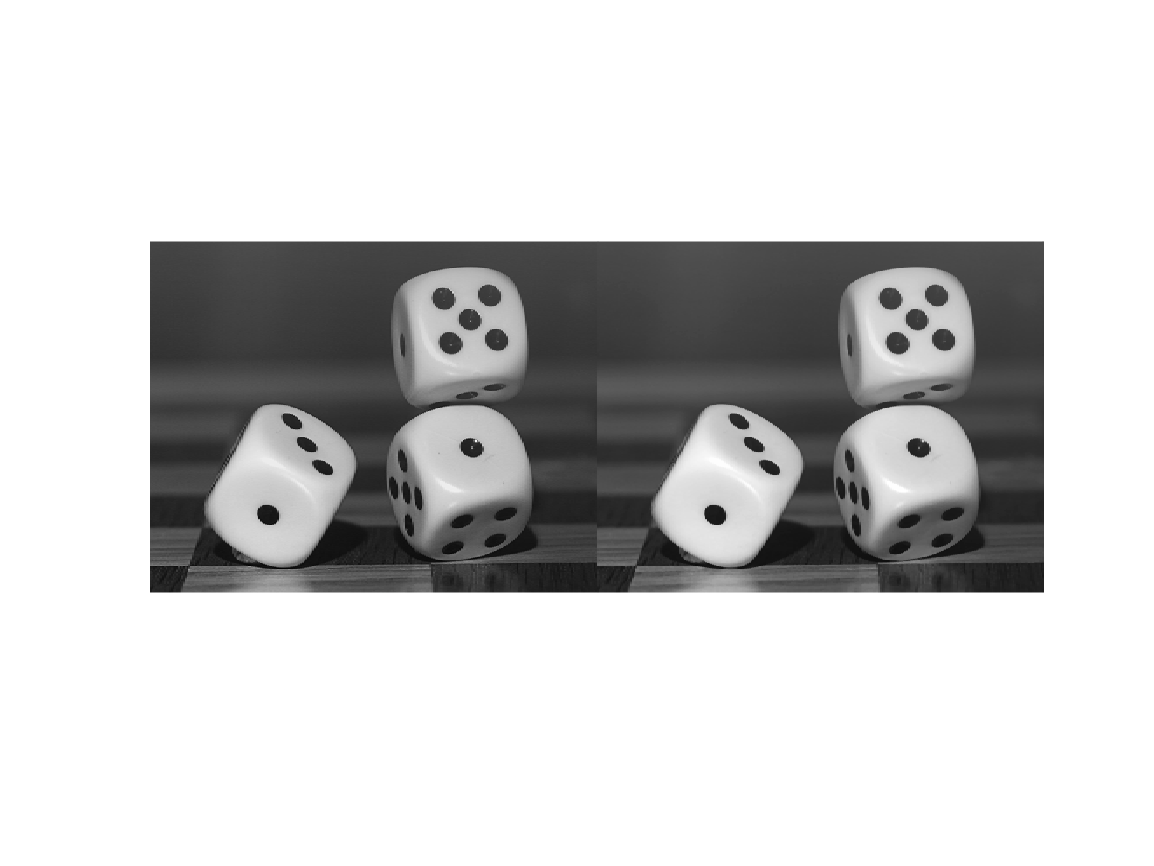

%Performs median filtering for noise reduction.
NoiseRemovalImage=medfilt2(Gi);
imshowpair(im,NoiseRemovalImage,"montage")

####     3. Sharpening

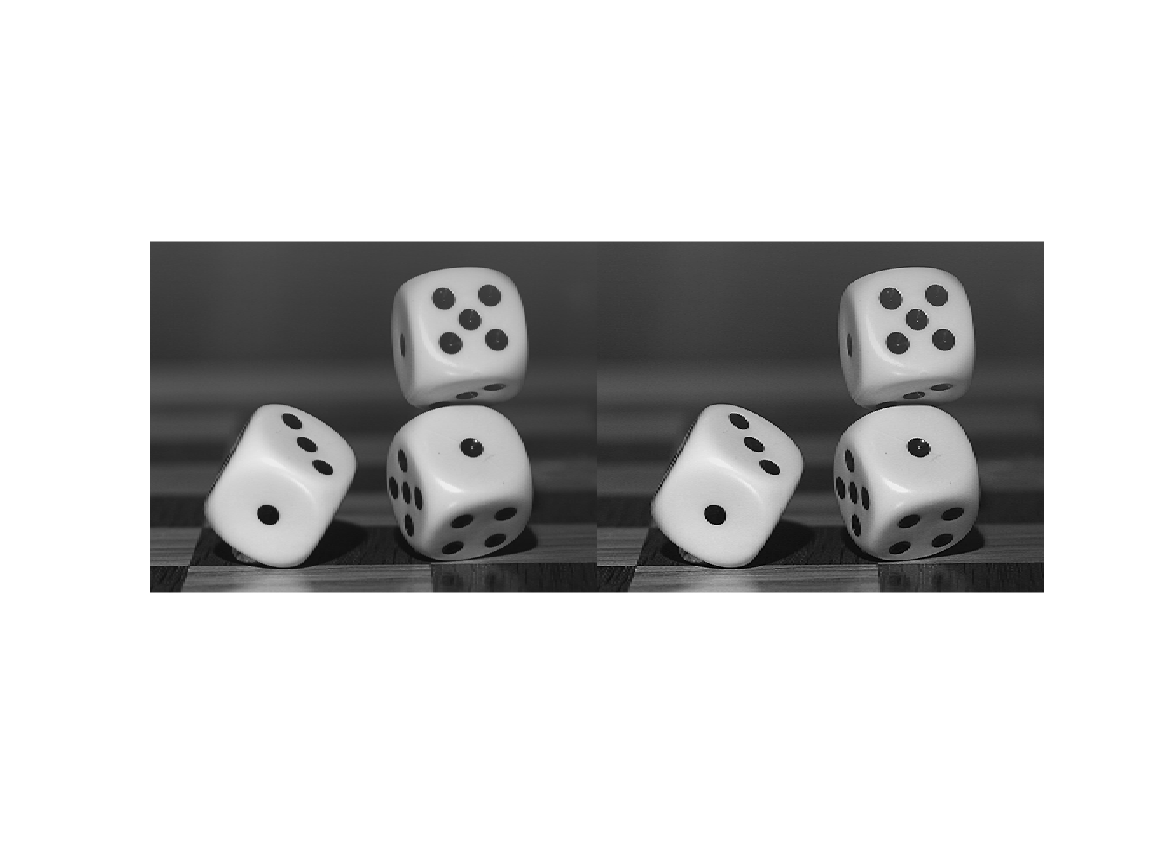

%Enhances the sharpness of an image.
SharpenImage=imsharpen(Gi);
imshowpair(im,SharpenImage,"montage")

####     4.Edge Detection

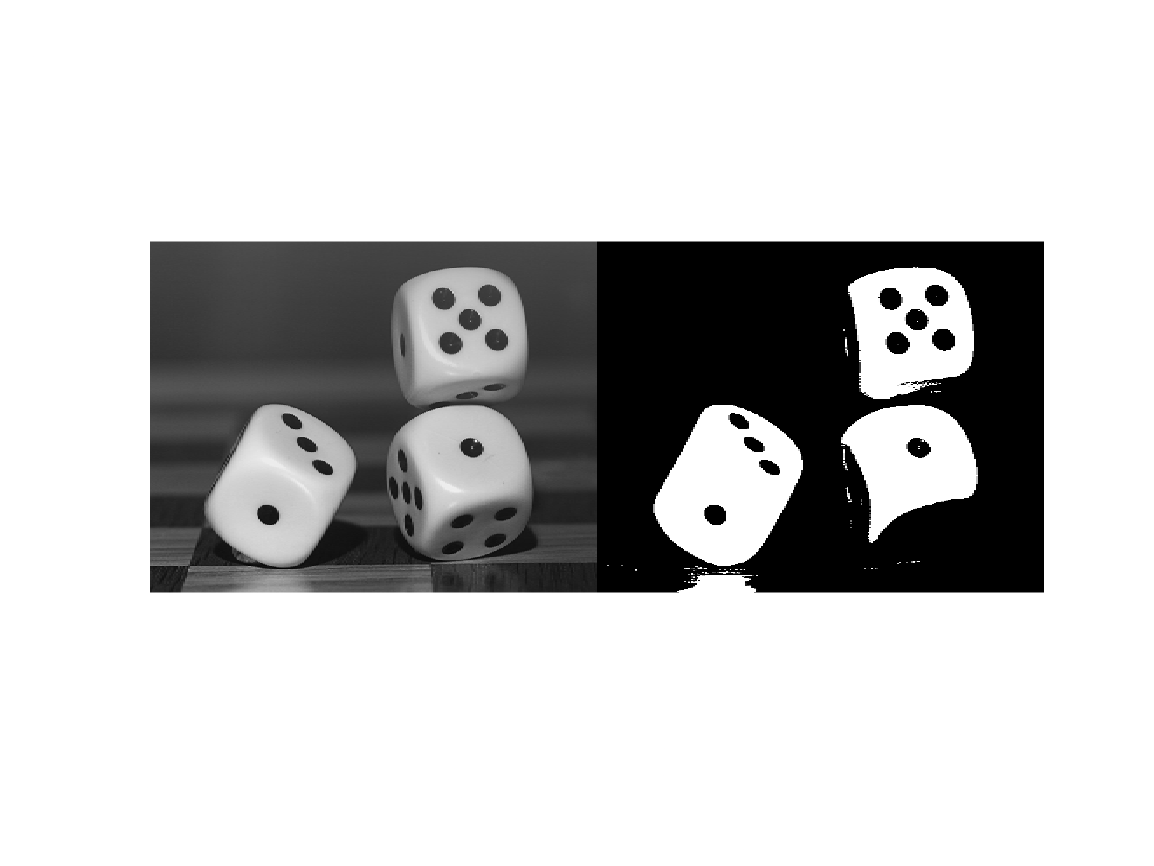

% Detect images in images
EdgeDetectedImage=imsegkmeans(Gi,2);
imshowpair(im,EdgeDetectedImage,"montage")

### 5.save result into workspace

%imwrite function used for save into workspace
imwrite(HistEquImage,"Result1.png")

### 6.Reference links for all filters and functions

To read Image

[https://www.mathworks.com/help/matlab/ref/imread.html](https://www.mathworks.com/help/matlab/ref/imread.html)

To show Image

[https://www.mathworks.com/help/matlab/ref/imshow.html](https://www.mathworks.com/help/matlab/ref/imshow.html)

Histogram Equalization

[https://www.mathworks.com/help/images/ref/histeq.html](https://www.mathworks.com/help/images/ref/histeq.html)

Noise Removal

[https://www.mathworks.com/help/images/ref/medfilt2.html](https://www.mathworks.com/help/images/ref/medfilt2.html)

Sharpening

[https://www.mathworks.com/help/images/ref/imsharpen.html](https://www.mathworks.com/help/images/ref/imsharpen.html)

Edge detection

[https://www.mathworks.com/help/images/ref/imsegkmeans.html](https://www.mathworks.com/help/images/ref/imsegkmeans.html)

imwrite funtion

[https://www.mathworks.com/help/matlab/ref/imwrite.html](https://www.mathworks.com/help/matlab/ref/imwrite.html)